# Sesion 2 Examples

# Example 2.1

The figure shows a frame **{B}** that is rotated relative to the frame **{A}** about  by 30 degrees. If the point in the **{B}** frame is , obtain the point  in the **{A}** reference frame.

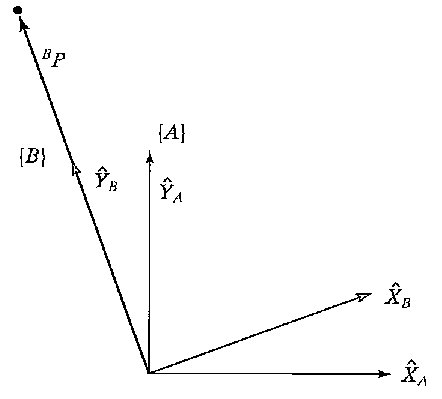

## Rotation

We calculate the rotation matrix which relates the frame **{B}** to **{A}**.

theta=30*pi/180; % radians
AB_R = [    cos(theta)  -sin(theta) 0;
            sin(theta)  cos(theta)  0;
            0           0           1;]

AB_R =     0.8660   -0.5000         0
    0.5000    0.8660         0
         0         0    1.0000


## Position vector in {A}

Given

            
B_P = [0 2 0]'

B_P =      0
     2
     0


## Position vector in {B}

We calculate  as

A_P = AB_R * B_P

A_P =    -1.0000
    1.7321
         0


# Example 2.2

The figure shows a frame **{B}** which is rotated relative to frame **{A}** about Z by 30 degrees, and translated 10 units in , and 5 units in . Find  where .

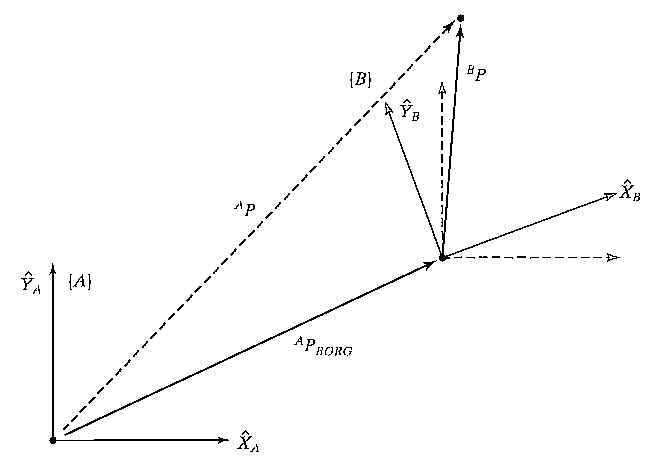

## Rotation

We obtain the rotation matrix about the Z-axis

theta=30*pi/180;
AB_R = [    cos(theta)  -sin(theta) 0;
            sin(theta)  cos(theta)  0;
            0           0           1;]

AB_R =     0.8660   -0.5000         0
    0.5000    0.8660         0
         0         0    1.0000


## Translation

Defining the position vector from the frame **{A}** to **{B}** 

AB_P = [ 10 5 0]'

AB_P =     10
     5
     0


## Homogeneous Transformation

We can compute the homogeneous transform  which relates the two systems using the rotation and translation

AB_T = [AB_R, AB_P;
        0   0   0   1]

AB_T =     0.8660   -0.5000         0   10.0000
    0.5000    0.8660         0    5.0000
         0         0    1.0000         0
         0         0         0    1.0000


## Point definition in {B}

Given , we operate with the extended vector to work with homogeneous transformations.

B_P = [3 7 0 1]'

B_P =      3
     7
     0
     1


## Point calculation in {A}

We use the definition of {B} given above as a transformation.

A_P = AB_T * B_P

A_P =     9.0981
   12.5622
         0
    1.0000


The result of this operation is a extended vector. If we want to obtain the vector which defines the point

A_P(1:3)

ans =     9.0981
   12.5622
         0


# Example 2.3

The figure shows a vector . We wish to compute the vector  obtained by rotating this vector about the Z-axis by 30 degrees.

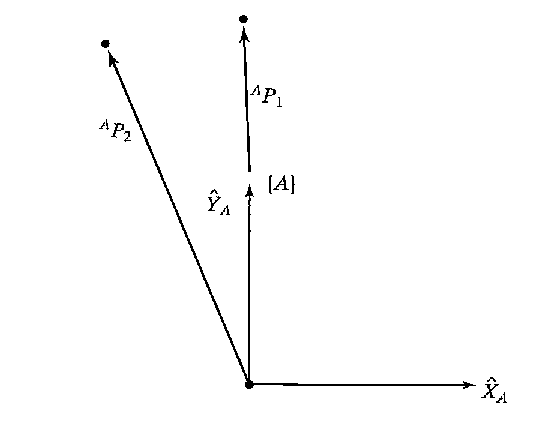

## Rotation

The rotation matrix which rotates vectors by 30 degrees about  is the same as the rotation matrix which describes a frame rotated 30 degrees about  relative to the reference frame. Thus the correct rotational operator is

theta=30*pi/180;
Rz = [      cos(theta)  -sin(theta) 0;
            sin(theta)  cos(theta)  0;
            0           0           1;]

Rz =     0.8660   -0.5000         0
    0.5000    0.8660         0
         0         0    1.0000


Which yields the same results as the RoboticToolbox command

Rz = rotz(30*pi/180)

Rz =     0.8660   -0.5000         0
    0.5000    0.8660         0
         0         0    1.0000


## Point P1 definition

Given 

A_P1 =  [0 2 0]'

A_P1 =      0
     2
     0


## Point P2 calculation

We calculate    as

A_P2 = Rz * A_P1

A_P2 =    -1.0000
    1.7321
         0


# Example 2.4

The figure shows a vector  . We wish to rotate it about   by 30 degrees, and translate it 10 units in   and 5 units in  . Find   where  

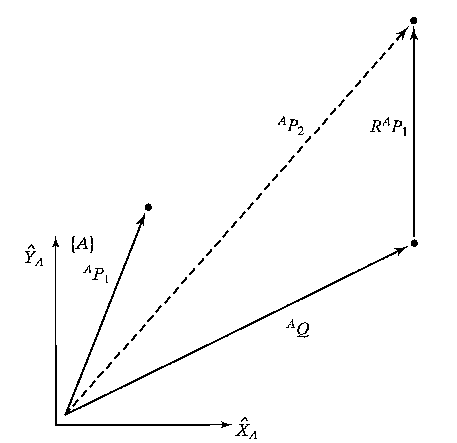

## Homogeneous transformation

We define the homogeneous transfomation based on the translation and rotation.

T = transl(10,5,0) * trotz (30*pi/180)

T =     0.8660   -0.5000         0   10.0000
    0.5000    0.8660         0    5.0000
         0         0    1.0000         0
         0         0         0    1.0000


## Point P1 definition

Given  . We use the extended vector.

A_P1 = [3 7 0 1]'

A_P1 =      3
     7
     0
     1


## Point P2 calculation

We use the homogeneous transformation as an operator   

A_P2 = T * A_P1

A_P2 =     9.0981
   12.5622
         0
    1.0000


# Example 2.5

The figure shows a frame **{B}** which is rotated relative to frame **{A}** about   by 30 degrees, and translated four units in   and three units in  . Thus we have a description of  . Find  .

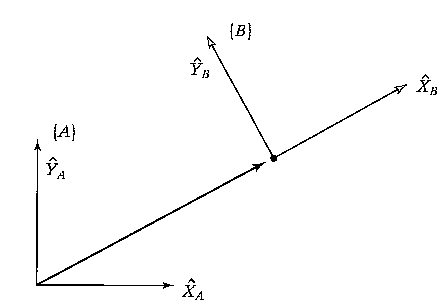

## Rotation

We define the rotation matrix with the RoboticToolbox about the axis Z

AB_R = rotz(30*pi/180)

AB_R =     0.8660   -0.5000         0
    0.5000    0.8660         0
         0         0    1.0000


## Translation

We define the relative displacement from **{A}** to **{B}**

AB_P = [4 3 0]'

AB_P =      4
     3
     0


## Homogeneous transformation

The frame defining {B} is

We can build the homogeneous transformation.

AB_T = [    AB_R,   AB_P;
            0 0 0,  1]

AB_T =     0.8660   -0.5000         0    4.0000
    0.5000    0.8660         0    3.0000
         0         0    1.0000         0
         0         0         0    1.0000


Or compute chaining the following operations

AB_T = transl(4,3,0) * trotz(30*pi/180)

AB_T =     0.8660   -0.5000         0    4.0000
    0.5000    0.8660         0    3.0000
         0         0    1.0000         0
         0         0         0    1.0000


## Inverse transformation

We compute the inverse of the transformation with the following expression

BA_T = [AB_R', -AB_R'*AB_P;
        0   0   0   1]

BA_T =     0.8660    0.5000         0   -4.9641
   -0.5000    0.8660         0   -0.5981
         0         0    1.0000         0
         0         0         0    1.0000


Which yields the same result as

BA_T = inv(AB_T)

BA_T =     0.8660    0.5000         0   -4.9641
   -0.5000    0.8660         0   -0.5981
         0         0    1.0000         0
         0         0         0    1.0000


# Femur

fv = stlread('femur.stl');

Homogeneous transfromation

Vertices = [fv.vertices'; ones(1, size(fv.vertices, 1))];
Vertices = transl(1000, 2000, 4000) * trotx(pi/2) * Vertices;
Vertices = Vertices(1:3,:);
fv.vertices = Vertices';

Compute center of mass

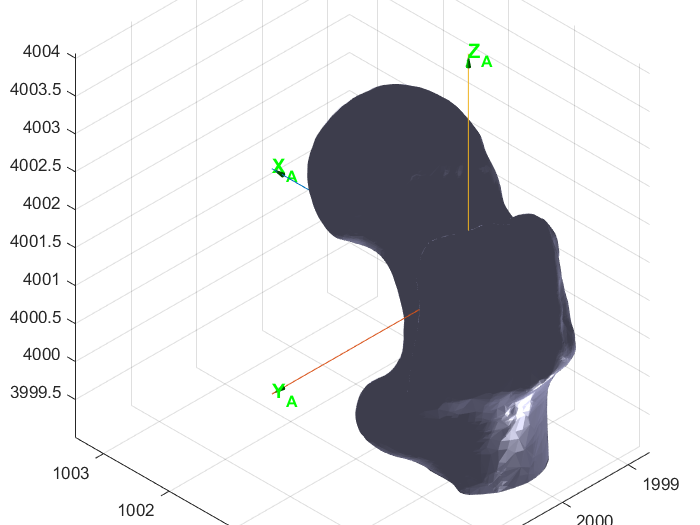

Center = [mean(Vertices(1,:)); mean(Vertices(2,:)); mean(Vertices(3,:));];
FA=eye(3);
A = transl(Center);
H1=trplot(FA, ... % Build frame FA with all the options
    'frame', 'A', ...
    'color', 'g',...
    'text_opts', {'FontSize', 12, 'FontWeight', 'bold'},...
    'length',3,...
    'arrow',...
    'axis',[-1 1 -1 1 -1 1],...
    'view',[150,30],...
    'width', 1.2);
trplot(A, H1,'handle',H1)

hold on
patch(fv,'FaceColor',       [0.8 0.8 1.0], ...
         'EdgeColor',       'none',        ...
         'FaceLighting',    'gouraud',     ...
         'AmbientStrength', 0.15);

% Add a camera light, and tone down the specular highlighting
camlight('headlight');
material('shiny');
alpha 1
axis equal
% Fix the axes scaling, and set a nice view angle
axis('image');
view([-135 35]);

.